close all;
clear;
clc;


## Question 2

## Part 1

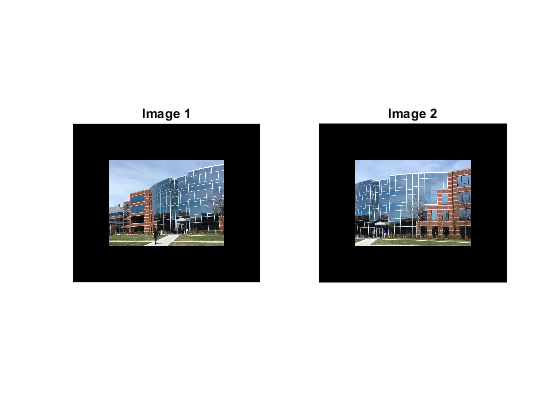

building1 = padarray(im2double(imread("building\building1.JPG")), [200,200,0]);
building2 = padarray(im2double(imread("building\building2.JPG")), [200,200,0]);

figure();
subplot(1,2,1);
imshow(building1, []);
title("Image 1");

subplot(1,2,2);
imshow(building2, []);
title("Image 2");

## Part 2

addpath('sift');

building1_gray = rgb2gray(building1);
building2_gray = rgb2gray(building2);

[frames1,descr1] = sift(building1_gray);
[frames2,descr2] = sift(building2_gray);


## Part 3

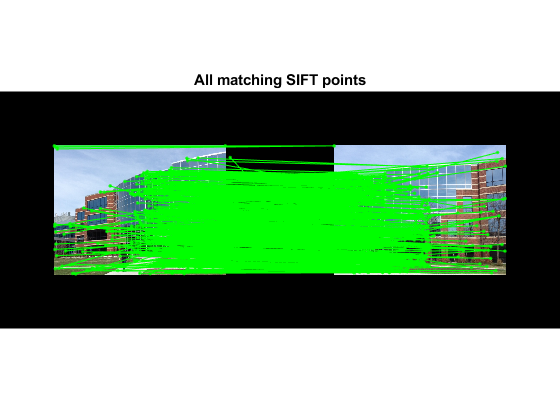


matches = siftmatch(descr1, descr2);
figure();
plotmatches(building1, building2, frames1, frames2, matches);
title('All matching SIFT points');

## Part 5

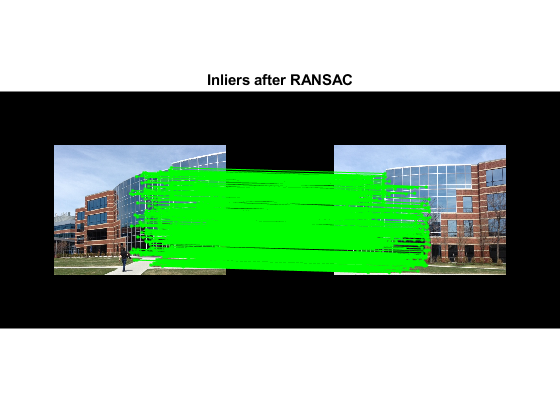

[H, inliers] = RANSAC(matches, frames1, frames2, 1000);
figure();
plotmatches(building1, building2, frames1, frames2, matches(:,inliers));
title('Inliers after RANSAC');

## Part 6-7

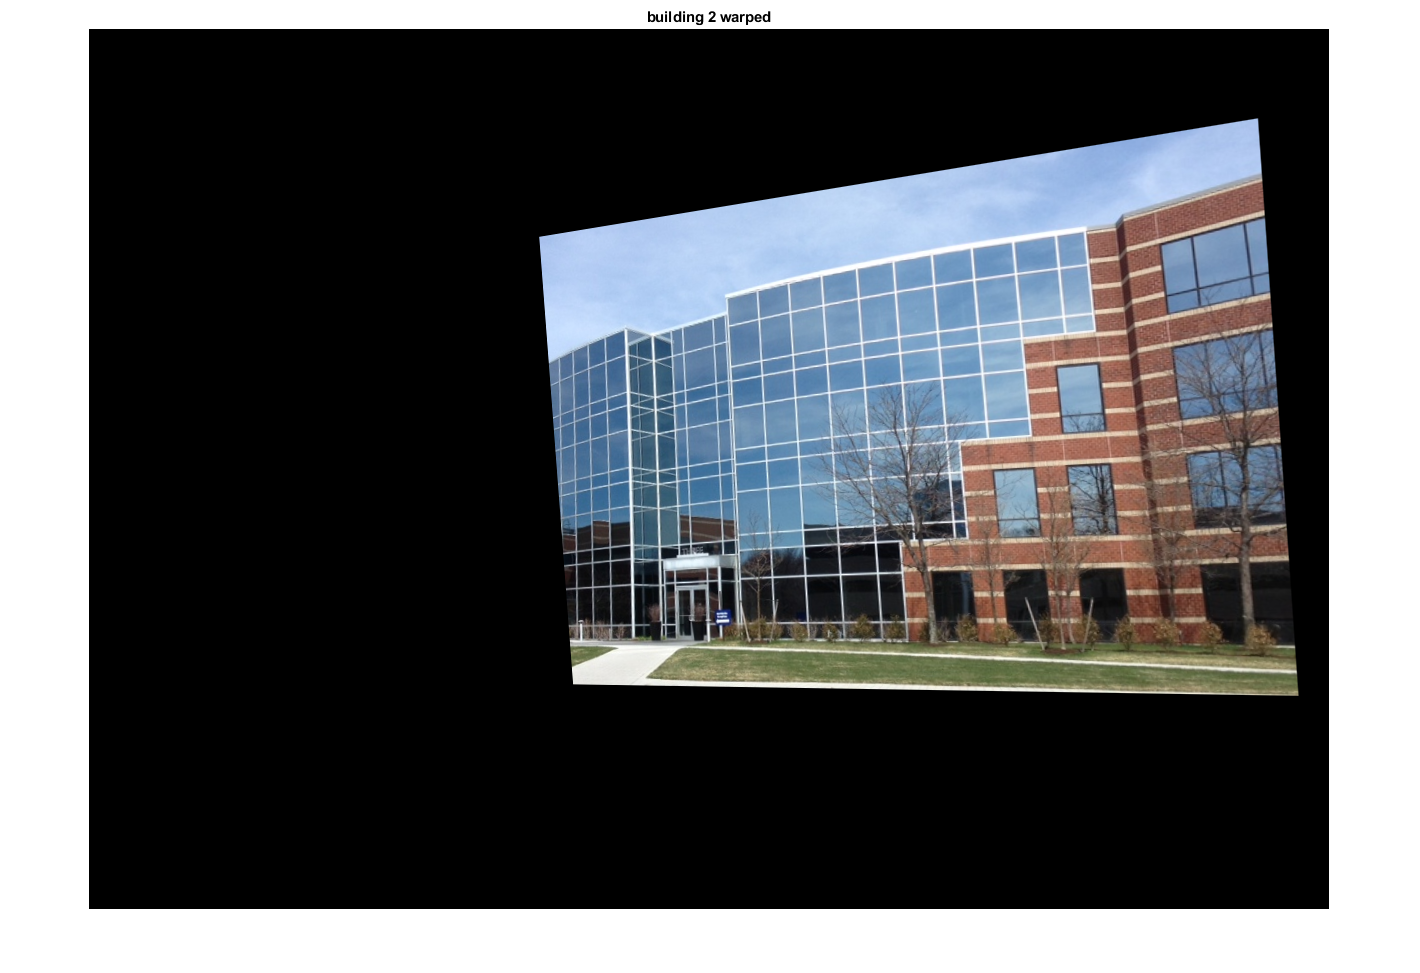

building2_warp = warpImage(building2, H);
figure();
imshow(building2_warp , []);
title('Building 2 warped');

## Part 8

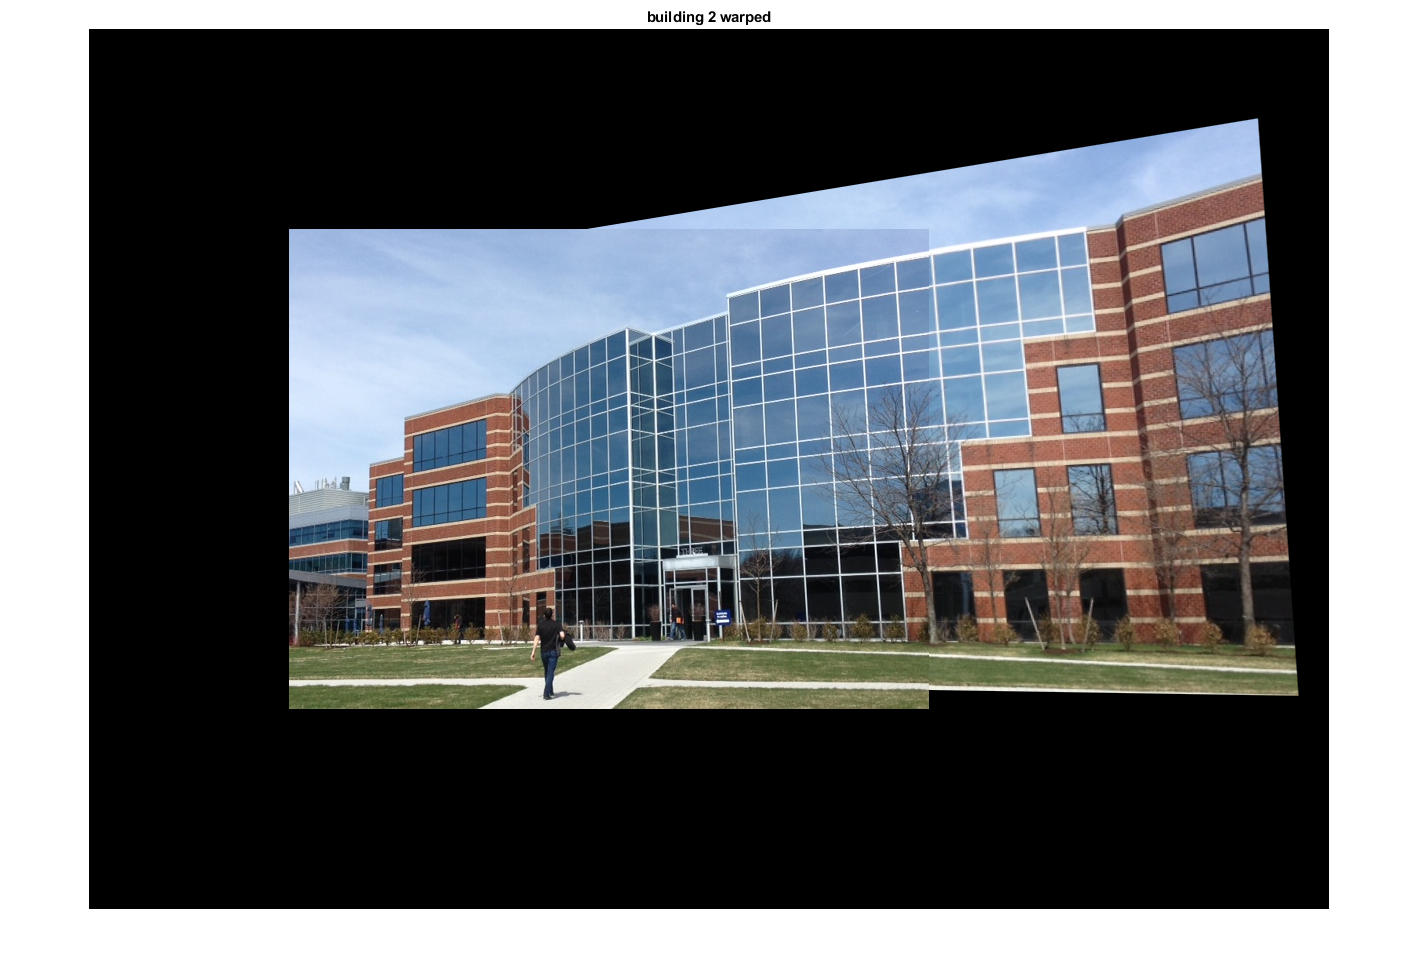

final_image = stitchImages(building1, building2_warp);
figure();
imshow(final_image , []);
title('Final result');